# Supplement B1: Tests on ideal signals to show the efficiency of the Fourier transform algorithm

Supplementary material to "Simulation of NMR spectra at zero- and ultra-low field from A to Z – a tribute to Prof. Konstantin L’vovich Ivanov" [https://doi.org/10.5194/mr-2022-18](https://doi.org/10.5194/mr-2022-18)

*Q. Stern and K. Sheberstov*

This script aims at showing that the Fourier transform is accurately computed. It shows:

- That the frequency axis is accurately computed regardless of the number of points in the FID

- That a window function must be applied to the FID to avoid a baseline shift in the Fourier transform and consequent bias in the signal integration

## Effect of zero filling and verification of the frequency axis

This section first computes the time domain signal *St* of an oscillating signal with frequency *nu0* and a decoherence time constant *T2*. The signal is sampled with *N* points from 0 to *tmax*. 

nu0=10;
T2=6; tmax=30;
N=2^15;
t=linspace(0,tmax,N)'; St=zeros(N,1);
St=St+cos(t*2*pi*nu0).*exp(-t/T2);

The signal is Fourier transformed using the function *FFT* (defined at the bottom of the code), with different values of the zero filling *N0*. The real parts of the resulting curves are ploted on the same graph.

The intensity of the signal decreases linearly with the number of points in the Fourier transform (here, *N0*). So that all curves superimpose, each curve is multiplied by the number of points of the Fourier transform *N0*.

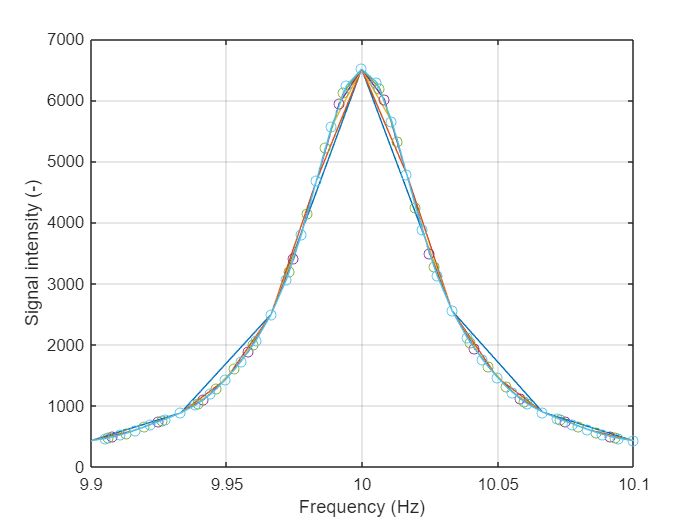

figure
for i=1:6
    N0=N*i;
    [nu,Snu_1]=FFT(t,St,N0);
    plot(nu,real(Snu_1)*N0,'o-'), hold on
end
hold off
ylabel('Signal intensity (-)')
xlabel('Frequency (Hz)')
x=0.1; xlim(nu0+[-x +x]), grid on

The plot shows that all the curves superimpose perfectly and that the frequency of the signal is precisely *nu0*, as expected. The user may play with the frequency *nu0* and choosing arbitrarily long *T2* values, the signal will always appear at *nu0* (provided *tmax* is chosen to be at least 5**T2*).

This shows that the computation of the Fourier transform and of the frequency axis are precise.

## Verification of the consistency of the integration

This section first computes the time domain signal *St* of oscillating signals with a frequency list *nu0* with a decoherence time constant *T2*. The signal is sampled with *N* points from 0 to *tmax*.

nu0=[5 25 50];
T2=6; tmax=80;
N=2^15; N0=N*16;
t=linspace(0,tmax,N)'; St=zeros(N,1);
for i=1:length(nu0)
    St=St+cos(t*2*pi*nu0(i)).*exp(-t/T2);
end

The signal is Fourier transformed using the functions *FFT* and *FFT_CleanBaseline* (defined at the bottom of the code) with *N0* points.

[nu,Snu_1]=FFT_CleanBaseline(t,St,N0);
[nu,Snu_2]=FFT(t,St,N0);
Sreal_1=real(Snu_1);
Sreal_2=real(Snu_2);

The real part of the Fourier transform is plotted. The veritical dashed lines show the area of integration of each signal which will be used later, which is defined based on the full width at half maximum of the signal (FWHM) to go from -W*FWHM to +W*FWHM.

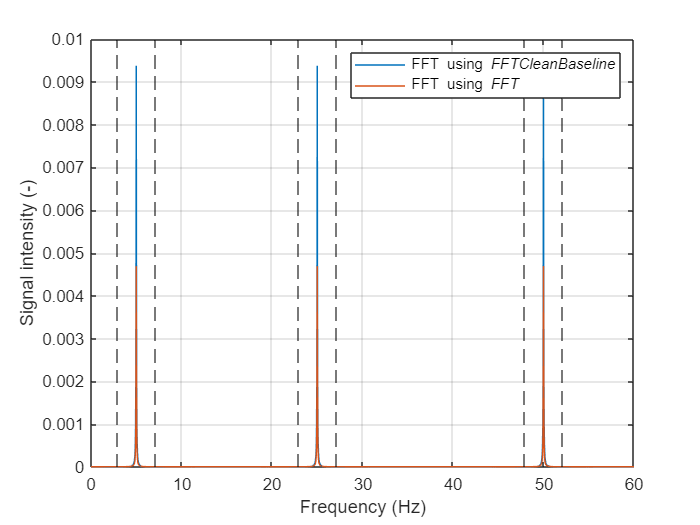

W=40;
figure
plot(nu,Sreal_1), hold on
plot(nu,Sreal_2), hold off
grid on
xlim([0 60])
ylabel('Signal intensity (-)'), xlabel('Frequency (Hz)')
for i=1:length(nu0)
    xline(nu0(i)-W/pi/T2,'k--')
    xline(nu0(i)+W/pi/T2,'k--')
end
legend({'FFT using {\itFFTCleanBaseline}','FFT using {\itFFT}'})

*FFT_CleanBaseline yield*s a signal twice as intense as *FFT*. However, without zooming at the foot of the signals, there is no reason to think that one algorithm is better than the other one.

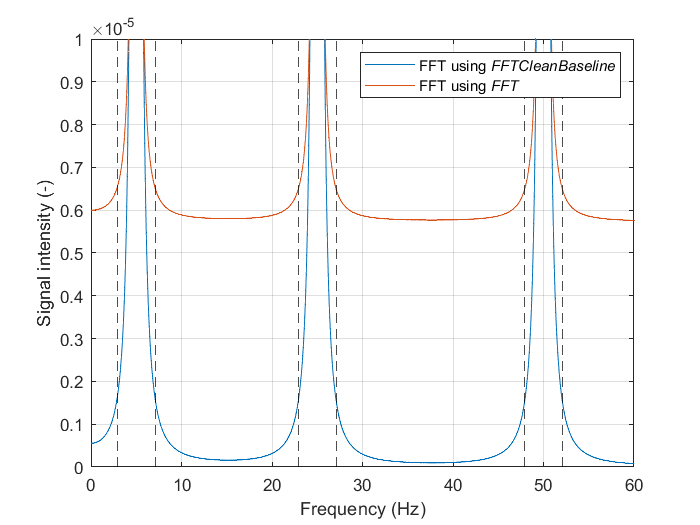

figure
plot(nu,Sreal_1), hold on
plot(nu,Sreal_2), hold off
grid on
xlim([0 60]), ylim([0 1e-5])
ylabel('Signal intensity (-)'), xlabel('Frequency (Hz)')
for i=1:length(nu0)
    xline(nu0(i)-W/pi/T2,'k--')
    xline(nu0(i)+W/pi/T2,'k--')
end
legend({'FFT using {\itFFTCleanBaseline}','FFT using {\itFFT}'})

The zoom above reveals that the Fourier transform computed using *FFT* has a baseline shift while that computed using *FFT_CleanBaseline* appropriately tends towards 0 away form the spectral components.

This difference is reflected in the signal integrals that are computed using both Fourier transform algorithms. The intensity of the first point of the FID is, according to Fourier analysis, equal to the total integral of the spectrum. Because the time domain signal is the sum of three cosine waves with unit amplitude, the first point of hte FID is equal to 3:

St(1)

ans = 3

For both *FFT* and *FFT_CleanBaseline*, the total sum of the spectrum is equal to the first point of the FID.

In the case of *FFT_CleanBaseline*:

sum(Sreal_1)

ans = 3.0000

while in the case of FFT:

sum(Sreal_2)

ans = 3.0000

When the individual resonances of the frequency domain signal computed with *FFT_CleanBaseline* are integrated, they tend towards 1, as they should:

SumOfTheIntegrals=0;
for i=1:length(nu0)
    Integral=sum(Sreal_1(nu>nu0(i)-W/pi/T2 & nu<nu0(i)+W/pi/T2));
    disp(['Integral of signal ' num2str(i) ': ' num2str(Integral)])
    SumOfTheIntegrals=SumOfTheIntegrals+Integral;
end

Integral of signal 1: 0.99258
Integral of signal 2: 0.99226
Integral of signal 3: 0.99214


and the sum of the three integrals tends towards 3:

SumOfTheIntegrals

SumOfTheIntegrals = 2.9770

To the contrary, when the individual resonances of the frequency domain signal computed with *FFT* are integrated, they tend towards significantly lower values than 1, because part of the integral moved into the baseline:

SumOfTheIntegrals=0;
for i=1:length(nu0)
    Integral=sum(Sreal_2(nu>nu0(i)-W/pi/T2 & nu<nu0(i)+W/pi/T2));
    disp(['Integral of signal ' num2str(i) ': ' num2str(Integral)])
    SumOfTheIntegrals=SumOfTheIntegrals+Integral;
end

Integral of signal 1: 0.52738
Integral of signal 2: 0.52722
Integral of signal 3: 0.52716


And the sum of the three integrals is barely higher than half what it should be:

SumOfTheIntegrals

SumOfTheIntegrals = 1.5818

function [nu,S]=FFT_CleanBaseline(t,I,N)
    % Converts to column vector
    I=I(:);
    
    % Window function to avoid baseline shift
    I=[I(1); 2*I(2:end)];
    
    % Sample length (s)
    T = (max(t)-min(t))/(length(I)-1);         
    
    % Frequency axis (Hz)
    nu = (0:N/2-1)/T/N;
    
    % Fourier transform
    S = fft(I,N)/N;
    
    % Remove negative frequencies
    S=2*S(1:N/2);
end
function [nu,S]=FFT(t,I,N)
    % Converts to column vector
    I=I(:);
    
    % Sample length (s)
    T = (max(t)-min(t))/(length(I)-1);         
    
    % Frequency axis (Hz)
    nu = (0:N/2-1)/T/N;
    
    % Fourier transform
    S = fft(I,N)/N;
    
    % Remove negative frequencies
    S=2*S(1:N/2);
end